Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector
S = sin(2*pi*50*t) + sin(2*pi*120*t)

S =          0    0.9936    1.5858    1.5795    1.0764    0.4122   -0.0312   -0.0353    0.3391    0.7908    0.9511    0.5958   -0.2197   -1.1771   -1.8559   -1.9511   -1.4328   -0.5603    0.2565    0.6733    0.5878    0.1837   -0.1827   -0.1890    0.2665    1.0000    1.6356    1.8070    1.3583    0.4344   -0.5878   -1.2913   -1.4321   -1.0577   -0.4693   -0.0489   -0.0462   -0.4409   -0.9559   -1.2138   -0.9511   -0.1727    0.8365    1.6533    1.9333    1.5878    0.8257    0.0385   -0.4102   -0.3755


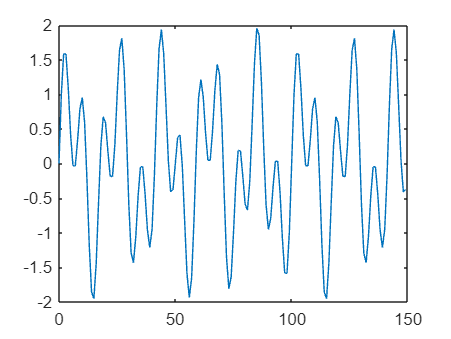


plot(Fs*t(1:150),S(1:150))

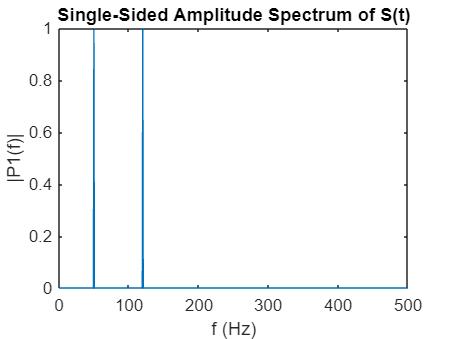


Y = fft(S);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')